Telecommunications Systems 2 Assignment 2024

Problem 1

clear

16-PAM

M_pam = 16;
i_max = 16;

d_min_pam = 0:0.01:0.7

d_min_pam =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


E_g_pam = d_min_pam.^2 / 4;

pam_avrg_power = E_g_pam * (M_pam.^2 - 1) ./ 3;

pam_max_power = ((2*i_max - M_pam - 1)*sqrt(E_g_pam)).^2;

papr_pam = pam_max_power ./ pam_avrg_power

papr_pam =        NaN    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471    2.6471


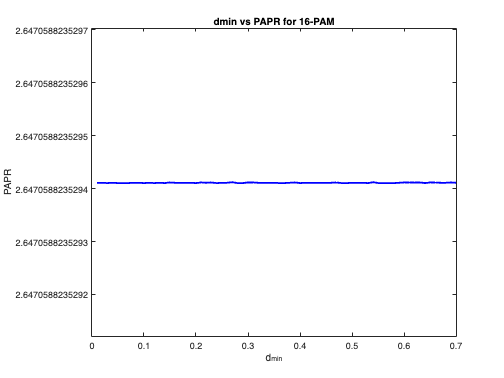


figure
plot(d_min_pam, papr_pam, "color", "blue", "LineWidth", 2)
title("dmin vs PAPR for 16-PAM")
xlabel("d_{min}")
ylabel("PAPR")

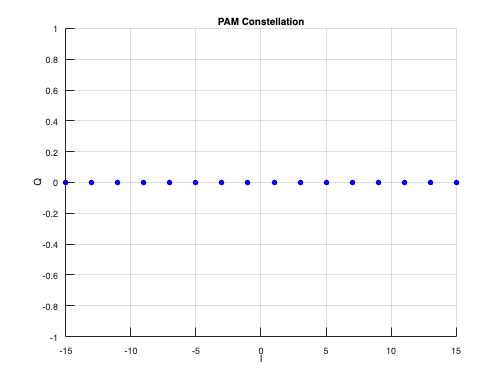


% Plot
E_g_pam_ = 1;
constellation_pam(1:8) = -(M_pam - (1:2:M_pam)) * sqrt(E_g_pam_);
constellation_pam(9:16) = (M_pam - (1:2:M_pam)) * sqrt(E_g_pam_);

figure;
scatter(constellation_pam, zeros(1, 16), 'b', 'filled');
xlabel('I');
ylabel('Q');
title('PAM Constellation');
grid on;

16-PSK

M_psk = 16;

d_min_psk = 0:0.01:0.7;

psk_avrg_power = (d_min_psk / (2 * sin(pi / M_psk))).^2

psk_avrg_power =          0    0.0007    0.0026    0.0059    0.0105    0.0164    0.0236    0.0322    0.0420    0.0532    0.0657    0.0795    0.0946    0.1110    0.1287    0.1478    0.1682    0.1898    0.2128    0.2371    0.2627    0.2897    0.3179    0.3475    0.3783    0.4105    0.4440    0.4788    0.5150    0.5524    0.5912    0.6312    0.6726    0.7153    0.7593    0.8046    0.8513    0.8992    0.9485    0.9991    1.0510    1.1042    1.1587    1.2145    1.2717    1.3301    1.3899    1.4510    1.5134    1.5771



E_s_psk = psk_avrg_power;
psk_max_power = psk_avrg_power;

papr_psk = psk_max_power ./ psk_avrg_power

papr_psk =    NaN     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


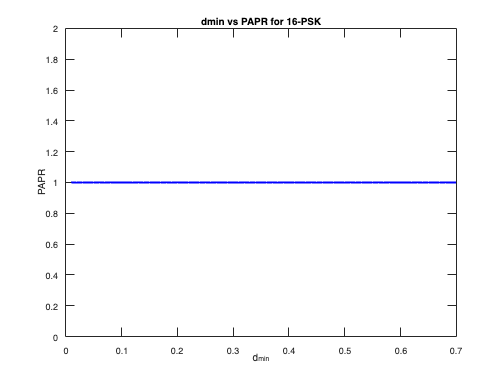


figure
plot(d_min_psk, papr_psk, "color", "blue", "LineWidth", 2)
title("dmin vs PAPR for 16-PSK")
xlabel("d_{min}")
ylabel("PAPR")

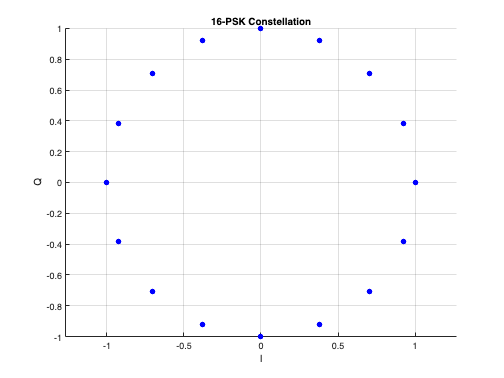


% Plot
E_s_psk_ = 1;
theta_psk = 2 * pi *((0:M_psk - 1) / M_psk); % Angle increment
constellation_psk = sqrt(E_s_psk_) * cos(theta_psk) + sqrt(E_s_psk_) * sin(theta_psk)*1j;

figure;
scatter(real(constellation_psk), imag(constellation_psk), 'b', 'filled');
xlabel('I');
ylabel('Q');
title('16-PSK Constellation');
grid on;
axis equal;

16-QAM 

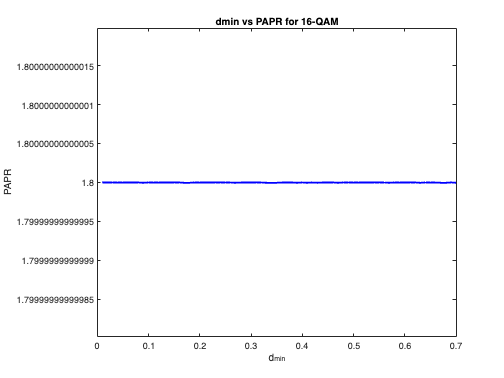

M_qam = 16;
d_min_qam = 0:0.01:0.7;

qam_avrg_power = d_min_qam.^2 * (M_qam - 1) / 6;

qam_max_power = 9 * d_min_qam.^2 / 2;

papr_qam = qam_max_power ./ qam_avrg_power;

figure
plot(d_min_qam, papr_qam, "color", "blue", "LineWidth", 2)
title("dmin vs PAPR for 16-QAM")
xlabel("d_{min}")
ylabel("PAPR")

16-CQAM,  N=4

M_cqam = 16;
dmin_cqam = 0:0.01:0.6

dmin_cqam =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


N_cqam = 4;

n = M_cqam / N_cqam;

% R1
R1 = dmin_cqam / (2 * sin(pi / n))

R1 =          0    0.0071    0.0141    0.0212    0.0283    0.0354    0.0424    0.0495    0.0566    0.0636    0.0707    0.0778    0.0849    0.0919    0.0990    0.1061    0.1131    0.1202    0.1273    0.1344    0.1414    0.1485    0.1556    0.1626    0.1697    0.1768    0.1838    0.1909    0.1980    0.2051    0.2121    0.2192    0.2263    0.2333    0.2404    0.2475    0.2546    0.2616    0.2687    0.2758    0.2828    0.2899    0.2970    0.3041    0.3111    0.3182    0.3253    0.3323    0.3394    0.3465



R1_avrg_power = R1.^2

R1_avrg_power =          0    0.0001    0.0002    0.0005    0.0008    0.0013    0.0018    0.0025    0.0032    0.0040    0.0050    0.0061    0.0072    0.0085    0.0098    0.0112    0.0128    0.0145    0.0162    0.0181    0.0200    0.0221    0.0242    0.0265    0.0288    0.0313    0.0338    0.0365    0.0392    0.0420    0.0450    0.0481    0.0512    0.0545    0.0578    0.0613    0.0648    0.0685    0.0722    0.0761    0.0800    0.0841    0.0882    0.0924    0.0968    0.1012    0.1058    0.1104    0.1152    0.1201



x1 = R1 * cos(pi / n);

y1 = sqrt(3) * dmin_cqam / 2;

% R2
R2 = x1 + y1

R2 =          0    0.0137    0.0273    0.0410    0.0546    0.0683    0.0820    0.0956    0.1093    0.1229    0.1366    0.1503    0.1639    0.1776    0.1912    0.2049    0.2186    0.2322    0.2459    0.2595    0.2732    0.2869    0.3005    0.3142    0.3278    0.3415    0.3552    0.3688    0.3825    0.3961    0.4098    0.4235    0.4371    0.4508    0.4644    0.4781    0.4918    0.5054    0.5191    0.5327    0.5464    0.5601    0.5737    0.5874    0.6011    0.6147    0.6284    0.6420    0.6557    0.6694



R2_avrg_power = R2.^2

R2_avrg_power =          0    0.0002    0.0007    0.0017    0.0030    0.0047    0.0067    0.0091    0.0119    0.0151    0.0187    0.0226    0.0269    0.0315    0.0366    0.0420    0.0478    0.0539    0.0605    0.0674    0.0746    0.0823    0.0903    0.0987    0.1075    0.1166    0.1261    0.1360    0.1463    0.1569    0.1679    0.1793    0.1911    0.2032    0.2157    0.2286    0.2418    0.2555    0.2695    0.2838    0.2986    0.3137    0.3292    0.3450    0.3613    0.3779    0.3949    0.4122    0.4299    0.4480



d2 = 2 * R2 * sin(pi / n);

% R3
R3 = sqrt(dmin_cqam.^2 + R1.^2 -2*dmin_cqam.*R1*cos(11*pi/12));

R3_avrg_power = R3.^2;

% R4

R4_avrg_power = 4 - R1_avrg_power - R2_avrg_power - R3_avrg_power

R4_avrg_power =     4.0000    3.9995    3.9979    3.9953    3.9916    3.9869    3.9812    3.9744    3.9665    3.9576    3.9477    3.9367    3.9247    3.9116    3.8975    3.8823    3.8661    3.8488    3.8305    3.8111    3.7907    3.7693    3.7468    3.7232    3.6986    3.6730    3.6463    3.6186    3.5898    3.5600    3.5291    3.4972    3.4642    3.4302    3.3952    3.3591    3.3219    3.2837    3.2445    3.2042    3.1629    3.1205    3.0771    3.0326    2.9871    2.9405    2.8929    2.8442    2.7945    2.7438



R4 = sqrt(R4_avrg_power)

R4 =     2.0000    1.9999    1.9995    1.9988    1.9979    1.9967    1.9953    1.9936    1.9916    1.9894    1.9869    1.9841    1.9811    1.9778    1.9742    1.9703    1.9662    1.9618    1.9572    1.9522    1.9470    1.9415    1.9357    1.9296    1.9232    1.9165    1.9095    1.9023    1.8947    1.8868    1.8786    1.8701    1.8612    1.8521    1.8426    1.8328    1.8226    1.8121    1.8012    1.7900    1.7784    1.7665    1.7542    1.7414    1.7283    1.7148    1.7009    1.6865    1.6717    1.6564


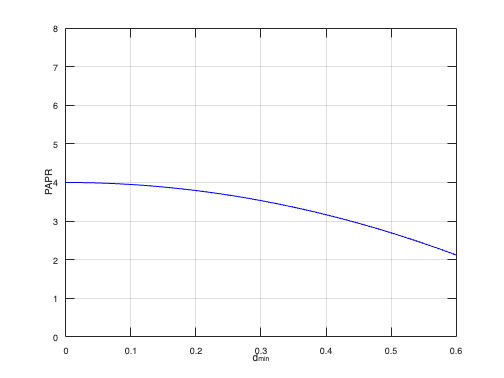


papr2 = R4_avrg_power;

figure
plot(dmin_cqam, papr2, "color", "blue", "LineWidth", 1)
xlabel("d_{min}")
ylabel("PAPR")
ylim([0,8])
grid on

16-CQAM,  N=8

M_cqam = 16;
dmin_cqam = 0:0.01:0.45

dmin_cqam =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500


N_cqam = 8;

n = M_cqam / N_cqam;

% R1
R1 = dmin_cqam / 2;
R1_avrg_power = R1.^2

R1_avrg_power =          0    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0016    0.0020    0.0025    0.0030    0.0036    0.0042    0.0049    0.0056    0.0064    0.0072    0.0081    0.0090    0.0100    0.0110    0.0121    0.0132    0.0144    0.0156    0.0169    0.0182    0.0196    0.0210    0.0225    0.0240    0.0256    0.0272    0.0289    0.0306    0.0324    0.0342    0.0361    0.0380    0.0400    0.0420    0.0441    0.0462    0.0484    0.0506



% R2
R2 = dmin_cqam * sqrt(3) / 2;
R2_avrg_power = R2.^2

R2_avrg_power =          0    0.0001    0.0003    0.0007    0.0012    0.0019    0.0027    0.0037    0.0048    0.0061    0.0075    0.0091    0.0108    0.0127    0.0147    0.0169    0.0192    0.0217    0.0243    0.0271    0.0300    0.0331    0.0363    0.0397    0.0432    0.0469    0.0507    0.0547    0.0588    0.0631    0.0675    0.0721    0.0768    0.0817    0.0867    0.0919    0.0972    0.1027    0.1083    0.1141    0.1200    0.1261    0.1323    0.1387    0.1452    0.1519



% R3
R3 = sqrt(dmin_cqam.^2 + R1.^2 - 2*dmin_cqam.*R1*cos(2*pi/3));
R3_avrg_power = R3.^2

R3_avrg_power =          0    0.0002    0.0007    0.0016    0.0028    0.0044    0.0063    0.0086    0.0112    0.0142    0.0175    0.0212    0.0252    0.0296    0.0343    0.0394    0.0448    0.0506    0.0567    0.0632    0.0700    0.0772    0.0847    0.0926    0.1008    0.1094    0.1183    0.1276    0.1372    0.1472    0.1575    0.1682    0.1792    0.1906    0.2023    0.2144    0.2268    0.2396    0.2527    0.2662    0.2800    0.2942    0.3087    0.3236    0.3388    0.3544



% R4
R4 = dmin_cqam + R1;
R4_avrg_power = R4.^2

R4_avrg_power =          0    0.0002    0.0009    0.0020    0.0036    0.0056    0.0081    0.0110    0.0144    0.0182    0.0225    0.0272    0.0324    0.0380    0.0441    0.0506    0.0576    0.0650    0.0729    0.0812    0.0900    0.0992    0.1089    0.1190    0.1296    0.1406    0.1521    0.1640    0.1764    0.1892    0.2025    0.2162    0.2304    0.2450    0.2601    0.2756    0.2916    0.3080    0.3249    0.3422    0.3600    0.3782    0.3969    0.4160    0.4356    0.4556



% R5
R5 = sqrt((2*dmin_cqam).^2 + R2.^2);
R5_avrg_power = R5.^2

R5_avrg_power =          0    0.0005    0.0019    0.0043    0.0076    0.0119    0.0171    0.0233    0.0304    0.0385    0.0475    0.0575    0.0684    0.0803    0.0931    0.1069    0.1216    0.1373    0.1539    0.1715    0.1900    0.2095    0.2299    0.2513    0.2736    0.2969    0.3211    0.3463    0.3724    0.3995    0.4275    0.4565    0.4864    0.5173    0.5491    0.5819    0.6156    0.6503    0.6859    0.7225    0.7600    0.7985    0.8379    0.8783    0.9196    0.9619



% R6
R6 = sqrt((2*dmin_cqam).^2 + R1.^2 - 2*(2*dmin_cqam).*R1*cos(2*pi/3));
R6_avrg_power = R6.^2

R6_avrg_power =          0    0.0005    0.0021    0.0047    0.0084    0.0131    0.0189    0.0257    0.0336    0.0425    0.0525    0.0635    0.0756    0.0887    0.1029    0.1181    0.1344    0.1517    0.1701    0.1895    0.2100    0.2315    0.2541    0.2777    0.3024    0.3281    0.3549    0.3827    0.4116    0.4415    0.4725    0.5045    0.5376    0.5717    0.6069    0.6431    0.6804    0.7187    0.7581    0.7985    0.8400    0.8825    0.9261    0.9707    1.0164    1.0631



% R7
R7 = 2*dmin_cqam + R1;
R7_avrg_power = R7.^2

R7_avrg_power =          0    0.0006    0.0025    0.0056    0.0100    0.0156    0.0225    0.0306    0.0400    0.0506    0.0625    0.0756    0.0900    0.1056    0.1225    0.1406    0.1600    0.1806    0.2025    0.2256    0.2500    0.2756    0.3025    0.3306    0.3600    0.3906    0.4225    0.4556    0.4900    0.5256    0.5625    0.6006    0.6400    0.6806    0.7225    0.7656    0.8100    0.8556    0.9025    0.9506    1.0000    1.0506    1.1025    1.1556    1.2100    1.2656



% R8
R8_avrg_power = 8 - R1_avrg_power - R2_avrg_power - R3_avrg_power - R4_avrg_power - R5_avrg_power - R6_avrg_power - R7_avrg_power;
R8 = sqrt(R8_avrg_power)

R8 =     2.8284    2.8281    2.8269    2.8250    2.8224    2.8190    2.8149    2.8100    2.8043    2.7978    2.7906    2.7826    2.7738    2.7642    2.7538    2.7426    2.7306    2.7177    2.7040    2.6894    2.6739    2.6576    2.6404    2.6222    2.6031    2.5830    2.5619    2.5399    2.5167    2.4926    2.4673    2.4409    2.4133    2.3845    2.3545    2.3231    2.2904    2.2563    2.2207    2.1835    2.1448    2.1043    2.0619    2.0176    1.9713    1.9227


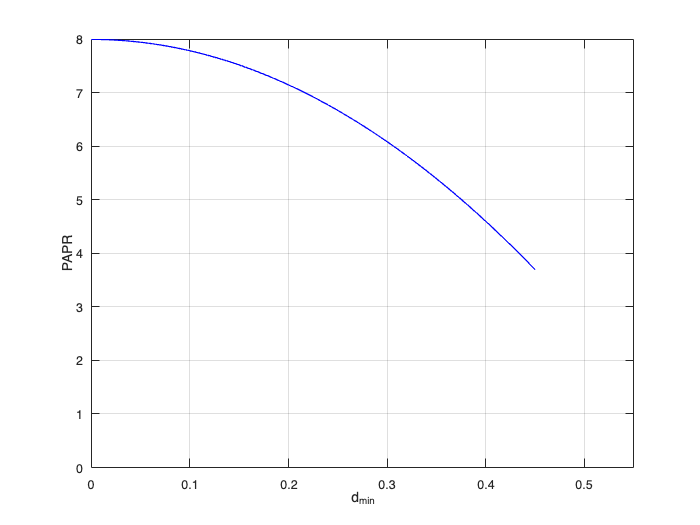


papr4 = R8_avrg_power;

figure
plot(dmin_cqam, papr4, "color", "blue", "LineWidth", 1)
xlabel("d_{min}")
ylabel("PAPR")
ylim([0,8])
xlim([0,0.55])
grid on